clc;
close all;
clear;
load("robot.mat");

## **Task 2**

initial position: -pi/2 pi/6 -pi/6 -pi/4 0 0 

joint_pos_init = [-pi/2, pi/6, -pi/6, -pi/4, 0, 0];
%joint_pos_init = transform_angle(joint_pos_init);

Intermediate Pose: 0 pi/3 0 0 0 0 

joint_pos_inter = [0, pi/3, 0, 0, 0, 0];
%joint_pos_inter = transform_angle(joint_pos_inter);

Final Pose : pi/4 pi/6 -pi/4 0 0 0 

joint_pos_final = [pi/4, pi/6, -pi/4, 0, 0, 0];
%joint_pos_final = transform_angle(joint_pos_final);

#### angle transform

homeconfig = homeConfiguration(robot);
Initial = homeconfig + joint_pos_init';
Intermediate = homeconfig + joint_pos_inter';
Final = homeconfig + joint_pos_final';

Step = 30;
tip_positions = zeros([Step*2,3]);
total_steps = Step * 2;
num_joints = length(homeconfig);

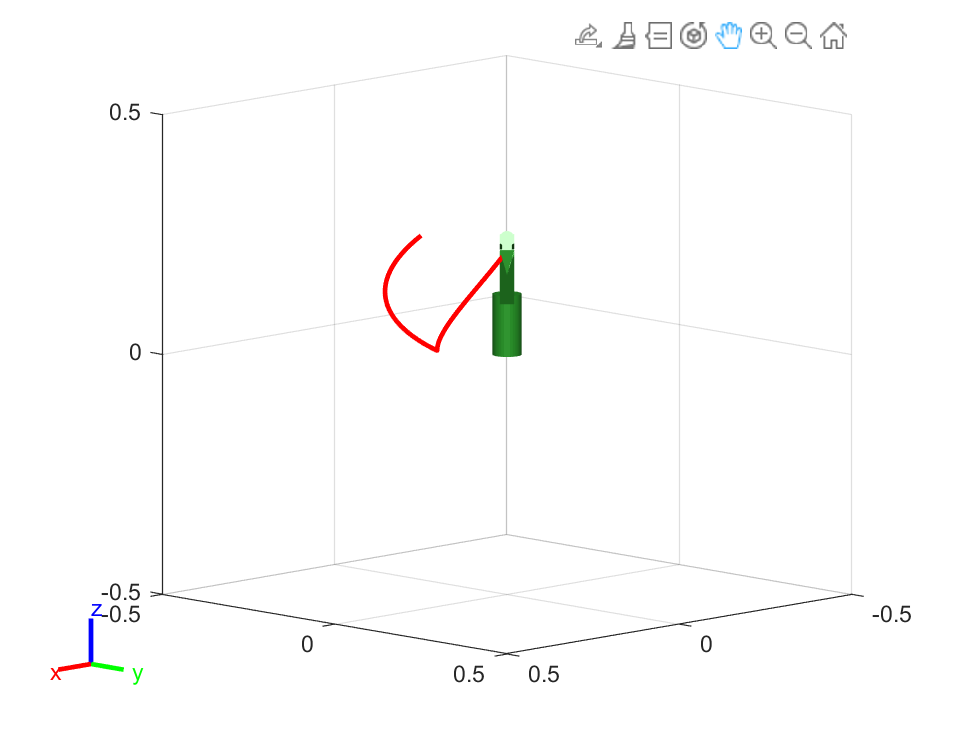

fig = figure('Color', [1 1 1]);
ax = axes('Parent', fig, 'DataAspectRatio', [1 1 1], 'XLim', [-0.5 0.5], 'YLim', [-0.5 0.5], 'ZLim', [-0.5 0.5]);
set(ax, 'XDir','reverse', 'YDir','reverse', 'ZDir','normal');
lighting gouraud;
light('Position',[1 1 1],'Style','infinite');
material dull;  
view(3);
view(ax, -45, 10);
grid on;
hold(ax, 'on');
zoom on;
pan on;
robotPlot = show(robot, Initial, 'Parent', ax, 'PreservePlot', false);
trajectoryPlot = plot3(ax, NaN, NaN, NaN, 'r', 'LineWidth', 2);

v = VideoWriter('Task2.avi');
v.FrameRate = 15;
open(v);

Qd = Intermediate - Initial;
for i = 1:Step
    q = Initial + Qd / Step * i;
    tip_positions(i,:) = cal_tip_positions(q);
    show(robot, q, 'Parent', ax, 'PreservePlot', false, "Collisions","on","Frames","off");
    set(trajectoryPlot, 'XData', tip_positions(1:i, 1), 'YData', tip_positions(1:i, 2), 'ZData', tip_positions(1:i, 3));
    drawnow;

    frame = getframe(gcf);
    writeVideo(v, frame);
end

Qd = Final - Intermediate;
for i = 1:Step
    q = Intermediate + Qd / Step * i;
    tip_positions(i+Step,:) = cal_tip_positions(q);
    show(robot, q, 'Parent', ax, 'PreservePlot', false, "Collisions","on","Frames","off");
    set(trajectoryPlot, 'XData', tip_positions(1:i+Step, 1), 'YData', tip_positions(1:i+Step, 2), 'ZData', tip_positions(1:i+Step, 3));
    drawnow;

    frame = getframe(gcf);
    writeVideo(v, frame);
end

hold(ax, 'off');

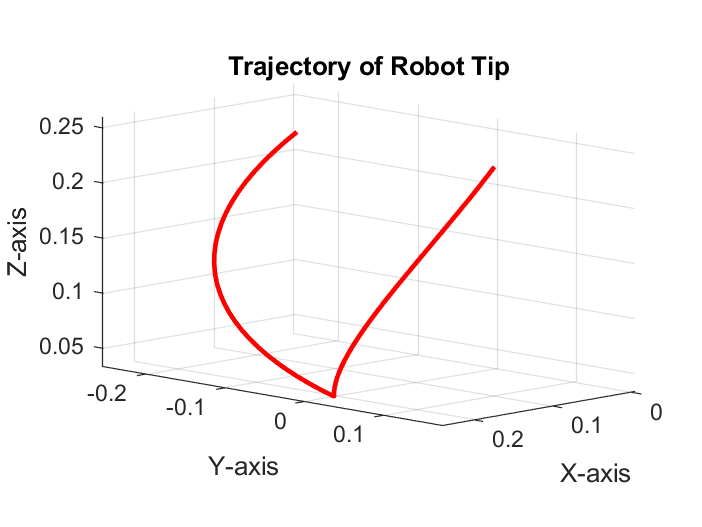

close(v);
figure('Color', [1 1 1]);
plot3(tip_positions(:, 1), tip_positions(:, 2), tip_positions(:, 3), 'r', 'LineWidth', 2);
grid on;
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');
title('Trajectory of Robot Tip');
axis equal;
view(135, 10); 

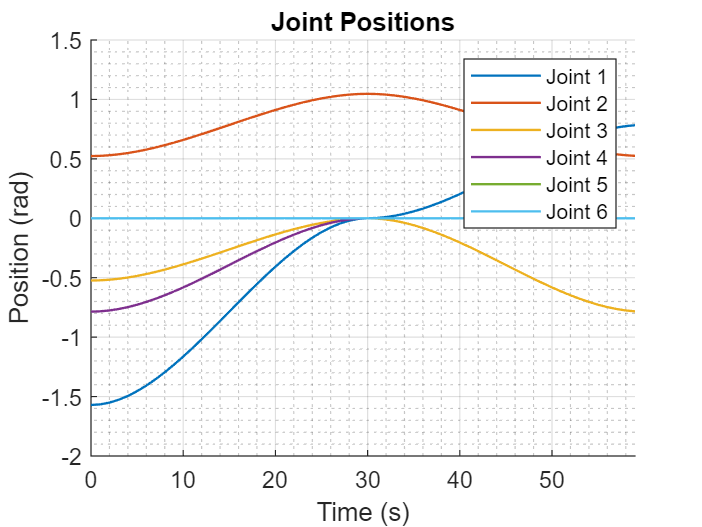

joint_positions = [];
joint_velocities = [];
for i = 1:num_joints
    [pos1, vel1] = calculateJointMotion(joint_pos_init(i), joint_pos_inter(i), Step);
    [pos2, vel2] = calculateJointMotion(joint_pos_inter(i), joint_pos_final(i), Step);

    joint_positions = [joint_positions; [pos1, pos2(2:end)]];
    joint_velocities = [joint_velocities; [vel1, vel2(2:end)]];
end

t = 0:(size(joint_positions, 2) - 1);
figure('Color', [1 1 1]);
hold on;
grid on;
grid minor;
for i = 1:num_joints
    plot(t, joint_positions(i,:), 'LineWidth', 1, 'DisplayName', ['Joint ' num2str(i)]);
end
xlim([0, 2*Step - 1]);
title("Joint Positions");
xlabel("Time (s)");
ylabel("Position (rad)");
legend;

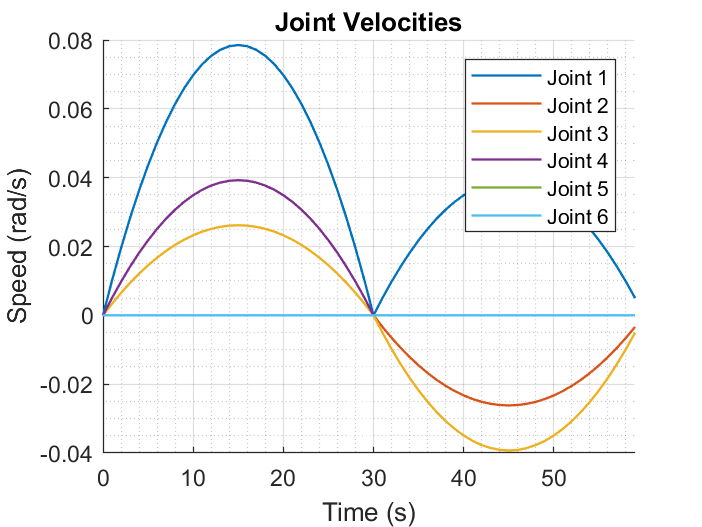


figure('Color', [1 1 1]);
hold on;
grid on;
grid minor;
for i = 1:num_joints
    plot(t, joint_velocities(i,:), 'LineWidth', 1, 'DisplayName', ['Joint ' num2str(i)]);
end
xlim([0, 2*Step - 1]);
title("Joint Velocities");
xlabel("Time (s)");
ylabel("Speed (rad/s)");
legend;

function to cal positions and velocities

function [positions, velocities] = calculateJointMotion(th0, thf, Step)
    a0 = th0;
    a1 = 0;
    a2 = 3*(thf-th0)/Step^2;
    a3 = -2*(thf-th0)/Step^3;
    t = 0:1:Step;
    positions = a0 + a1*t + a2*t.^2 + a3*t.^3;
    velocities = a1 + 2*a2*t + 3*a3*t.^2;
end

function to calculate transform matrix according to one line of the MDH table

function T = dh_transmatrix(a,alpha,d,theta)
    T = [   cos(theta),             -sin(theta),            0,           a;
            sin(theta)*cos(alpha),  cos(theta)*cos(alpha), -sin(alpha), -sin(alpha)*d;
            sin(theta)*sin(alpha),  cos(theta)*sin(alpha),  cos(alpha),  cos(alpha)*d;
            0,                      0,                      0,           1];
end

function to calculate one tip positions

function tip_position = cal_tip_positions(q)
d1 = 0.127;
a1 = 0.029; 
a2 = 0.108; 
a3 = 0.02; d4 = 0.168;
d6 = -0.02429;
dhparams = [0,   	   0,    	d1,      q(1);
                a1,       -pi/2,    0,        q(2);
                a2,        0,    	0,        q(3);
                a3,       -pi/2,    d4,      q(4);
                0,         pi/2,    0,        q(5);
                0,         pi/2,    d6,     q(6)];



tip_position = zeros([1,3]);
T = eye(4);
for j = 1:size(dhparams,1)
    T = T * dh_transmatrix(dhparams(j,1),dhparams(j,2),dhparams(j,3),dhparams(j,4));
end
for j = 1:3
    tip_position(1,j) = T(j,4);
end
end